clear


EjeManivelaA=readtable("MatLab cinetica\Reacciones manivela\A3-Eje-manivela-Der.txt","Delimiter"," ");

EjeManivelaA.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];
EjeManivelaB=readtable("MatLab cinetica\Reacciones manivela\B3-Eje-manivela-Der.txt","Delimiter"," ");

EjeManivelaB.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];
EjeManivelaC=readtable("MatLab cinetica\Reacciones manivela\C3-Eje-manivela-Der.txt","Delimiter"," ");

EjeManivelaC.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

BielaManivelaA=readtable("MatLab cinetica\Reacciones manivela\A3-Biela-manivela-Der.txt","Delimiter"," ");

BielaManivelaA.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];
BielaManivelaB=readtable("MatLab cinetica\Reacciones manivela\B3-Biela-manivela-Der.txt","Delimiter"," ");

BielaManivelaB.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];
BielaManivelaC=readtable("MatLab cinetica\Reacciones manivela\C3-Biela-manivela-Der.txt","Delimiter"," ");

BielaManivelaC.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];



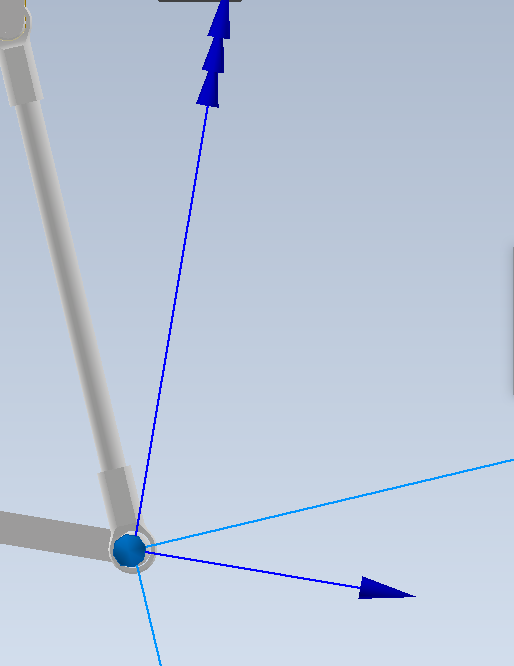

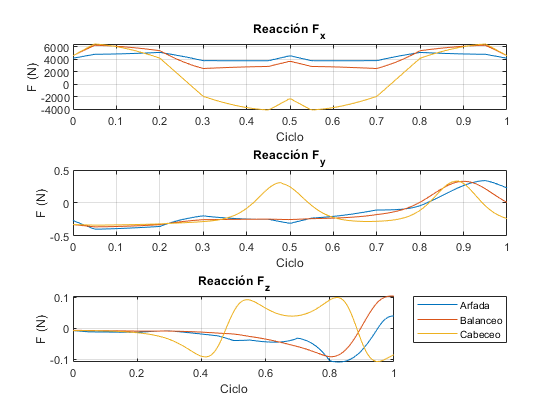



BielaManivelaAFx=BielaManivelaA.Fy;
BielaManivelaAFy=BielaManivelaA.Fz;
BielaManivelaAFz=-BielaManivelaA.Fx;

BielaManivelaBFx=BielaManivelaB.Fy;
BielaManivelaBFy=BielaManivelaB.Fz;
BielaManivelaBFz=-BielaManivelaB.Fx;

BielaManivelaCFx=BielaManivelaC.Fy;
BielaManivelaCFy=BielaManivelaC.Fz;
BielaManivelaCFz=-BielaManivelaC.Fx;


figure("Name","Biela Manivela")
subplot(3,1,1)
plot(linspace(0,1,160),BielaManivelaAFx)
hold on
plot(linspace(0,1,160),BielaManivelaBFx)
plot(linspace(0,1,160),BielaManivelaCFx)
hold off
title('Reacción F_x')
%ylim([-35 35])
xlabel('Ciclo')
ylabel('F (N)')
grid on
subplot(3,1,2)
plot(linspace(0,1,160),BielaManivelaAFy)
hold on
plot(linspace(0,1,160),BielaManivelaBFy)
plot(linspace(0,1,160),BielaManivelaCFy)
hold off
title('Reacción F_y')
xlabel('Ciclo')
ylabel('F (N)')
grid on
subplot(3,1,3)
plot(linspace(0,1,160),BielaManivelaAFz)
hold on
plot(linspace(0,1,160),BielaManivelaBFz)
plot(linspace(0,1,160),BielaManivelaCFz)
hold off
title('Reacción F_z')
xlabel('Ciclo')
ylabel('F (N)')
grid on
legend("Arfada","Balanceo","Cabeceo","Location","bestoutside")



EjeManivelaAFx=EjeManivelaA.Fx;
EjeManivelaAFy=-EjeManivelaA.Fy;
EjeManivelaAFz=-EjeManivelaA.Fz;

EjeManivelaBFx=EjeManivelaB.Fx;
EjeManivelaBFy=-EjeManivelaB.Fy;
EjeManivelaBFz=-EjeManivelaB.Fz;

EjeManivelaCFx=EjeManivelaC.Fx;
EjeManivelaCFy=-EjeManivelaC.Fy;
EjeManivelaCFz=-EjeManivelaC.Fz;


EjeManivelaAMx=EjeManivelaA.Mx/1000;
EjeManivelaAMy=-EjeManivelaA.My/1000;
EjeManivelaAMz=-EjeManivelaA.Mz/1000;

EjeManivelaBMx=EjeManivelaB.Mx/1000;
EjeManivelaBMy=-EjeManivelaB.My/1000;
EjeManivelaBMz=-EjeManivelaB.Mz/1000;

EjeManivelaCMx=EjeManivelaC.Mx/1000;
EjeManivelaCMy=-EjeManivelaC.My/1000;
EjeManivelaCMz=-EjeManivelaC.Mz/1000;


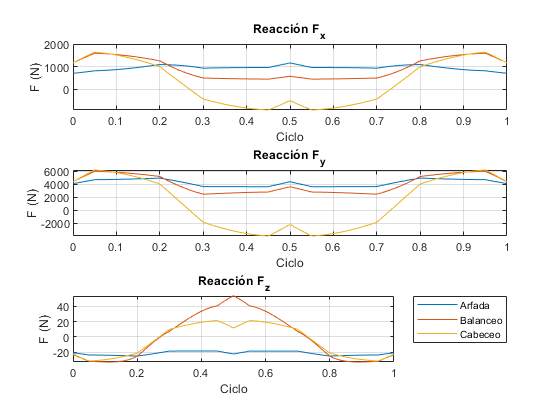


figure("Name","Eje manivela")
subplot(3,1,1)
plot(linspace(0,1,160),EjeManivelaAFx)
hold on
plot(linspace(0,1,160),EjeManivelaBFx)
plot(linspace(0,1,160),EjeManivelaCFx)
hold off
title('Reacción F_x')
%ylim([-35 35])
xlabel('Ciclo')
ylabel('F (N)')
grid on
subplot(3,1,2)
plot(linspace(0,1,160),EjeManivelaAFy)
hold on
plot(linspace(0,1,160),EjeManivelaBFy)
plot(linspace(0,1,160),EjeManivelaCFy)
hold off
title('Reacción F_y')
xlabel('Ciclo')
ylabel('F (N)')
grid on
subplot(3,1,3)
plot(linspace(0,1,160),EjeManivelaAFz)
hold on
plot(linspace(0,1,160),EjeManivelaBFz)
plot(linspace(0,1,160),EjeManivelaCFz)
hold off
title('Reacción F_z')
xlabel('Ciclo')
ylabel('F (N)')
grid on
legend("Arfada","Balanceo","Cabeceo","Location","bestoutside")

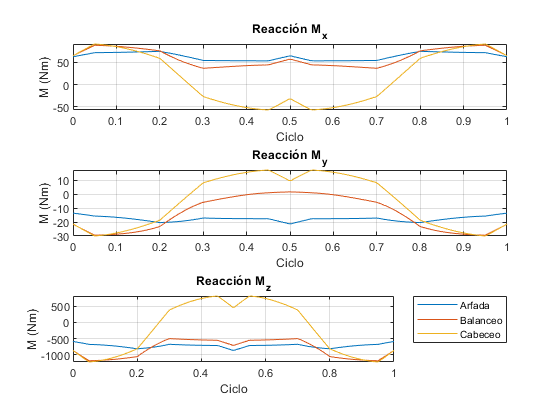


figure("Name","Momento eje manivela")
subplot(3,1,1)
plot(linspace(0,1,160),EjeManivelaAMx)
hold on
plot(linspace(0,1,160),EjeManivelaBMx)
plot(linspace(0,1,160),EjeManivelaCMx)
hold off
title('Reacción M_x')
%ylim([-35 35])
xlabel('Ciclo')
ylabel('M (Nm)')
grid on
subplot(3,1,2)
plot(linspace(0,1,160),EjeManivelaAMy)
hold on
plot(linspace(0,1,160),EjeManivelaBMy)
plot(linspace(0,1,160),EjeManivelaCMy)
hold off
title('Reacción M_y')
xlabel('Ciclo')
ylabel('M (Nm)')
grid on
subplot(3,1,3)
plot(linspace(0,1,160),EjeManivelaAMz)
hold on
plot(linspace(0,1,160),EjeManivelaBMz)
plot(linspace(0,1,160),EjeManivelaCMz)
hold off
title('Reacción M_z')
xlabel('Ciclo')
ylabel('M (Nm)')
grid on
legend("Arfada","Balanceo","Cabeceo","Location","bestoutside")